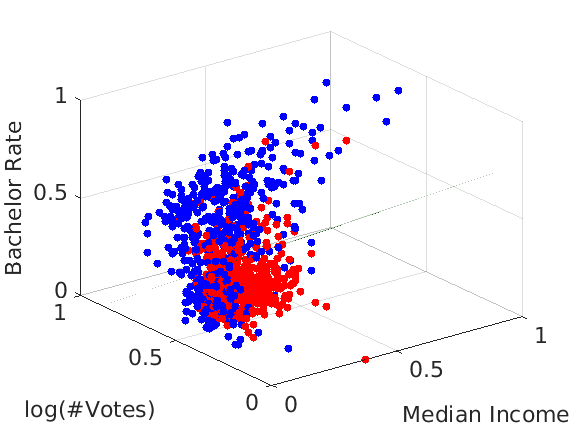

% retrieving data
[~,~, y, X] = Project1main_q2();

[n,dim] = size(X);
Y = (y*ones(1,dim+1)).*[X ones(n,1)];
lambda = 0.01;
fun = @(I,Y,w)fun0(I,Y,w,lambda);
gfun = @(I,Y,w)gfun0(I,Y,w,lambda);
Hvec = @(I,Y,w,v)Hvec0(I,Y,w,v,lambda);
nsteps = 1000;
nruns = 1000;

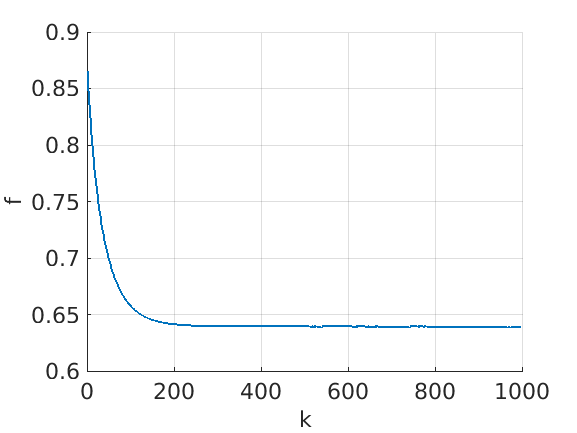

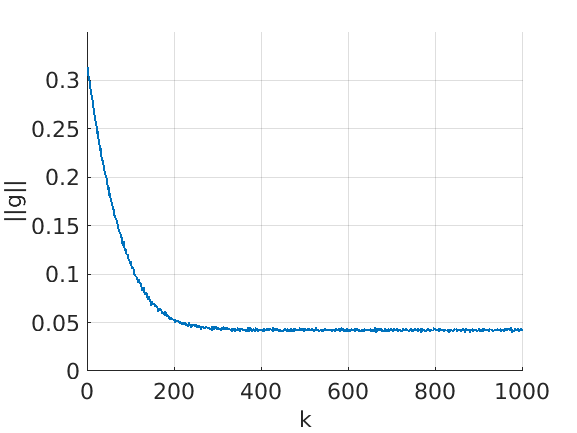

%% batch size:
%%% 1. 100;
batch_size = 100;
[fs, gs, runtime1] = SINewton_experiment([0.5;0.5;0.5;0.5],fun,gfun,Hvec,Y,batch_size,nsteps,nruns);
SGplotting(fs,gs,'si_batch_100')

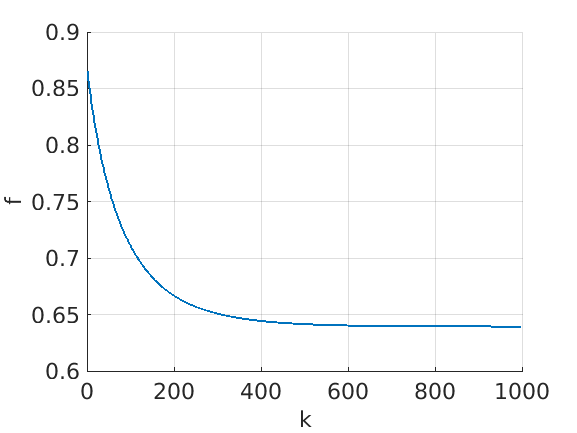

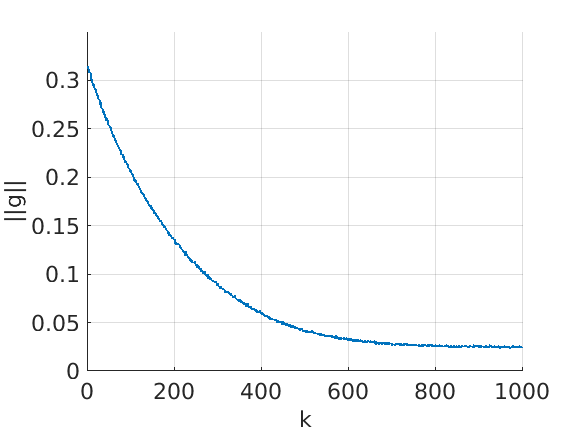

%%% 2. 250;
batch_size = 250;
[fs, gs, runtime2] = SINewton_experiment([0.5;0.5;0.5;0.5],fun,gfun,Hvec,Y,batch_size,nsteps,nruns);
SGplotting(fs,gs,'si_batch_250')

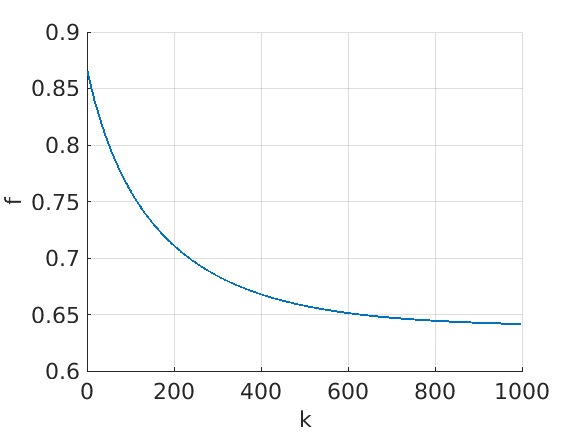

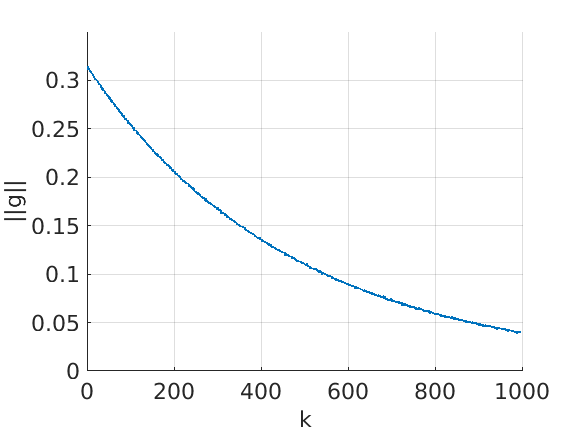

%%% 3. 500;
batch_size = 500;
[fs, gs, runtime3] = SINewton_experiment([0.5;0.5;0.5;0.5],fun,gfun,Hvec,Y,batch_size,nsteps,nruns);
SGplotting(fs,gs,'si_batch_500')

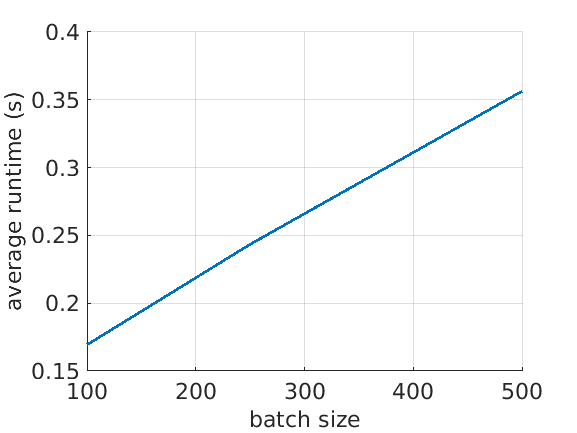

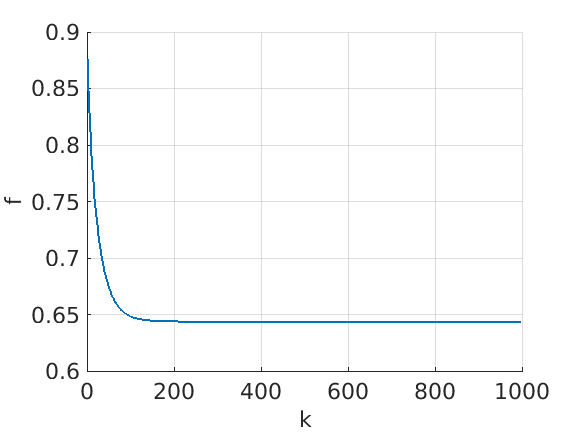

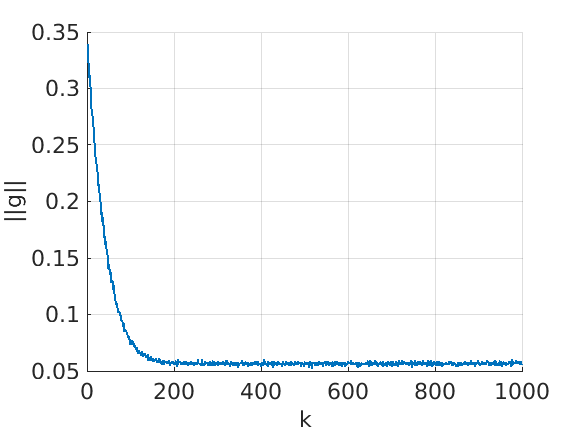

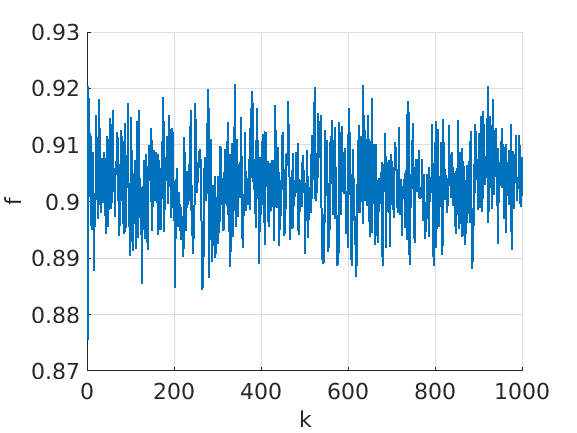

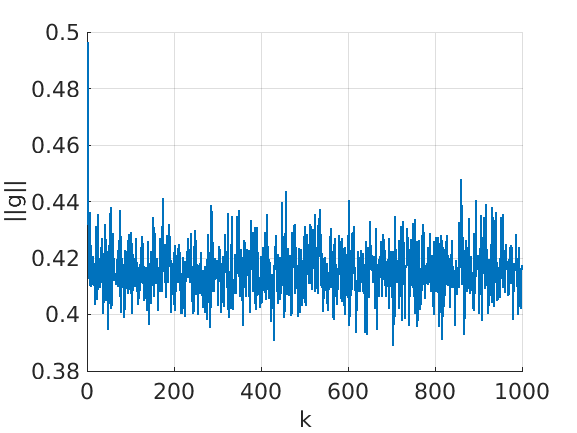

%%% batch size v.s runtime
figure;
hold on;
grid;
plot([100 250 500],[runtime1 runtime2 runtime3],'Linewidth',2);
fsz = 16;
set(gca,'Fontsize',fsz);
xlabel('batch size','Fontsize',fsz);
ylabel('average runtime (s)','Fontsize',fsz);
saveas(gcf, 'si_runtime.png');

function f = fun0(I,Y,w,lam) 
f = sum(log(1 + exp(-Y(I,:)* w)))/length(I) + 0.5*lam* (w'* w);
end

function g = gfun0(I,Y,w,lam) 
aux = exp(-Y(I,:)*w);
d1 = size(Y,2);
g = sum(-Y(I,:).*((aux./(1 + aux))*ones(1,d1)),1)'/length(I) + lam*w;
end

function Hv = Hvec0(I,Y,w,v,lam)
aux = exp(-Y(I,:)*w);
d1 = size(Y,2);
Hv = sum(Y(I,:).*((aux.*(Y(I,:)*v)./((1+aux).^2)).*ones(1,d1)),1)' + lam*v;
end